clear all
syms x(t) y(t) theta(t) Ff(t) N(t)

animate_it = 1;     % set to 1 to plot the animation
save_it = 0;        % set to 1 to save the animation

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

rG=[x(t);y(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(rG,t,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vG = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = diff(rG,t) == vG(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

The unknown functions (just the base functions, not derivatives) are: Ff(t),N(t),theta(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
Ff: 2.807963 Fft:0.000000
N: 8.542992 Nt:0.000000
theta: 1.396263 thetat:0.000000
x: -0.097830 xt:0.000000
y: 0.092630 yt:0.000000
Dthetat: 0.000000 Dthetatt:-30.313706
Dxt: 0.000000 Dxtt:2.807963
Dyt: 0.000000 Dytt:-1.267008


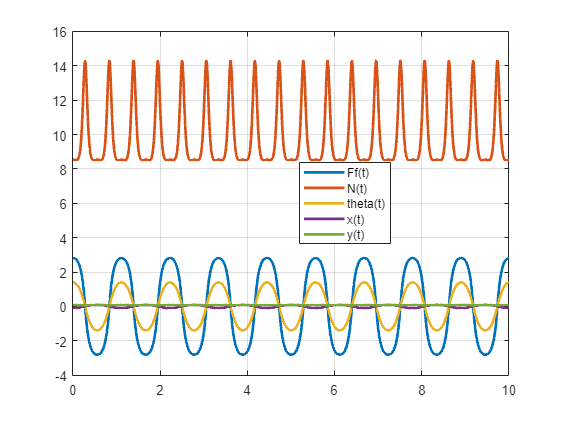

%Solve using the numerical solver.  The "unknown functions" are still x, y,
%theta, and the DE is second order in all of them.  So, you'll need to
%provide an initial condition for x and y.  Or whatever.  In any case,
%you'll need three state variables.  Essentially, you have said that we
%have to roll along the ground, but we have not said where the ground is. 

theta0 = 80*pi/180;
omega0 = 0;
temp = [-r*theta0;0;0] + [0;r;0] + [cos(theta0) -sin(theta0) 0;sin(theta0) cos(theta0) 0;0 0 1]*[0;-4*r/(3*pi);0];
x0 = temp(1);
y0 = temp(2);


soln=mechanicsAsDAE(DES,disp_const,vel_const,[0 10],{theta==theta0,diff(theta)==omega0,x==x0,y==y0});

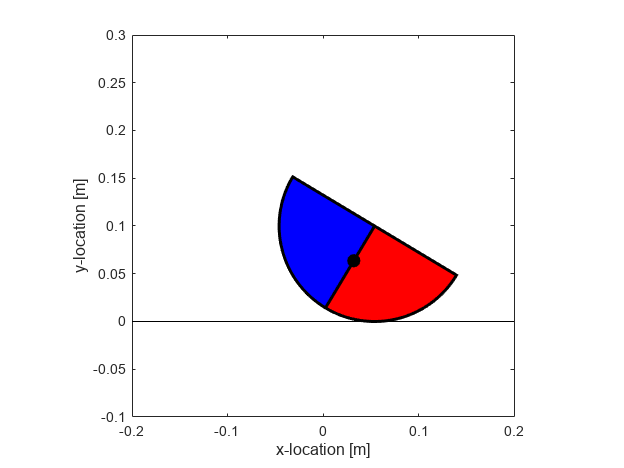

if animate_it == 1
    t_anim = linspace(min(soln.t),max(soln.t),1001)';
    theta_anim = interp1(soln.t,soln.theta,t_anim);
    rGx_anim = interp1(soln.t,soln.x,t_anim);
    rGy_anim = interp1(soln.t,soln.y,t_anim);
    func_animate_semi_cylinder(t_anim,theta_anim,rGx_anim,rGy_anim,r,save_it)
end

%If you notice above, the differential equation is really first order in x'
%and y'.  If you *really* don't want to solve for x and y (even though it
%is fine to just put any number you like in for x0 and y0) then you can
%formulate the problem that way. 


syms vx(t) vy(t) theta(t) Ff(t) N(t)

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

vG=[vx(t);vy(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(vG,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vGr = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = vG == vGr(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

soln=mechanicsAsDAE(DES,disp_const,vel_const,[0,20],{theta==theta0,diff(theta)==omega0});



%Go back to the original set up, in terms of x and y rather than vx and vy. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

rG=[x(t);y(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(rG,t,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vG = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = diff(rG,t) == vG(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];


%Once again, because you've formulated it this way, it is expected that
%you'll need four state variables.  Because the dependence is so
%simple, you can actually get away with 2.  Watch out though!  If you do this, the solver
%will say that it can set x(t) and y(t) to be anything it likes, and choose
%0!  You'll get the correct governingODEs, but there is no way to calculate
%x(t) and y(t) out of theta, so your postprocessing equations will be
%incorrect. 
[governingODEs,PPs]=analyzeSystem(DES,[],vel_const,[theta,diff(theta)]);
%This governing ODE is correct. 
vpa(governingODEs,2)
%Look at the last two entries for the post processing. It
%is just saying that x(t)=0 and y(t)=0. 
vpa(PPs,2)

%Now you can timestep. You can solve for theta fine out of governing ODE.
%Just don't trust the results in the postprocessing equations for x and y. 
soln=timeStepODESystem(governingODEs,[0,20],[theta==theta0,diff(theta)==omega0],PPs,0);
plot(soln.t,soln.theta,soln.t,soln.Ff,soln.t,soln.N,'LineWidth',2)
legend({"theta","Ff","N"},'Location','Best')
grid on


%You could have called x and y state variables, since they are in this
%formulation.  Now everything lines up, and the postprocessing equations
%can be trusted. 

[governingODEs,PPs]=analyzeSystem(DES,[],vel_const,[theta,diff(theta),x,y]);
vpa(governingODEs,2)
vpa(PPs,2)
%Now you can timestep.  You'll need to give initial conditions for x,y,
%because they are state variables. 

soln=timeStepODESystem(governingODEs,[0,20],[theta==theta0,diff(theta)==omega0,x==0,y==1],PPs,0);
plot(soln.t,soln.theta,soln.t,soln.Ff,soln.t,soln.N,soln.t,soln.x,soln.t,soln.y,'LineWidth',2)
legend({"theta","Ff","N","x","y"},'Location','Best')
grid on

%Finally, you could formulate the whole thing in terms of vx and vy like
%above, and proceed symbolically (ish). 

syms vx(t) vy(t) theta(t) Ff(t) N(t)

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

vG=[vx(t);vy(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(vG,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vGr = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = vG == vGr(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

[governingODEs,PPs]=analyzeSystem([DES],[],vel_const,[theta,diff(theta)])
soln=timeStepODESystem(governingODEs,[0,20],[theta==pi/4,diff(theta)==0],PPs);


function [] = func_animate_semi_cylinder(t,theta,rGx,rGy,r,save_it)

skip_frame = 1;

if save_it == 1
    %--------------------------------------------------------------------------
    % animate the results
    saveDirName = uigetdir('', ['Specify the directory where the ', ...
        'animations will be saved.']);

    %  Append a slash to the directory name ('/' for Mac, '\' for Windows):
    if isempty(strfind(saveDirName, '/')) == 0
        saveDirName = [saveDirName, '/'];
    else
        saveDirName = [saveDirName, '\'];
    end

    animObj = VideoWriter([saveDirName, 'rocking_semi_circle.avi']);
    open(animObj)
    skip_frame = 5;
end

% plot the angular displacements
figure(101)
clf
plot([-2*r 2*r],[0 0],'k')
xlabel('x-location [m]')
ylabel('y-location [m]')
axis equal
axis([-2*r 2*r -r 3*r])

%  Calculate how the locations of the disk's quadrants vary
%  over time, and arrange the Cartesian coordinates for the vertices in
%  arrays:

quadrant1 = [...
    0, r*cosd(180:270);...
    0, r*sind(180:270)];
quadrant2 = [...
    0, r*cosd(270:360);...
    0, r*sind(270:360)];

for k = 1:length(t)

    R_b_I = [cos(theta(k)), -sin(theta(k));sin(theta(k)), cos(theta(k))];

    rG = [rGx(k);rGy(k)];

    temp = rG + R_b_I*[0;4*r/(3*pi)] + R_b_I*quadrant1;
    q1x(k,:) = temp(1,:);
    q1y(k,:) = temp(2,:);

    temp = rG + R_b_I*[0;4*r/(3*pi)] + R_b_I*quadrant2;
    q2x(k,:) = temp(1,:);
    q2y(k,:) = temp(2,:);

end

%  Specify the quadrant colors:
c1 = [0, 0, 1];
c2 = [1, 0, 0];

%  Draw the disk, highlight the center G, and trace its path:
quad1 = patch('xdata', q1x(1,:), 'ydata', q1y(1,:), 'facecolor', ...
    c1, 'linewidth', 2);
quad2 = patch('xdata', q2x(1,:), 'ydata', q2y(1,:), 'facecolor', ...
    c2, 'linewidth', 2);
pointG = line('xdata', rGx(1), 'ydata', rGy(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'linewidth', 3);

for k = 1:skip_frame:length(t)
    set(quad1, 'xdata', q1x(k,:), 'ydata', q1y(k,:));
    set(quad2, 'xdata', q2x(k,:), 'ydata', q2y(k,:));
    set(pointG, 'xdata', rGx(k), 'ydata', rGy(k));
    drawnow

    if save_it == 1
        writeVideo(animObj, getframe(gcf));
    end
end

if save_it == 1
    close(animObj)
end
end